# Lista 1 - Parte 3

Autor: Francisco Castro

## Introdução

    Este documento refere-se à implementação do algoritmo de Salichev incremental com quatro amostras, sendo a continuação (parte 3) das listas computacionais já entregues como atividade da disciplina EES-60, ministrada pelo Prof. Dr. Jacques Waldmann em 2019.

## Método TRIAD

    Referente à Parte 1 da lista computacional.

metodoTRIAD;

## Estabilização vertical (Questão 1)

    Foi-se implementado, assim como na Parte 2 desta lista, um controlador com a finalidade de estabilizar o canal vertical dos sensores que, originalmente, produziam resultados extremamente divergentes quanto, principalmente, à altitude e a componente *down* da velocidade $V_{NED}$. Assumindo-se a presença artificial de um altímetro de suporte, atribui-se o valor da altitude inicial como o valor de altitude medido por este a cada instante a fim de implementar a referida estabilização.

    Nesta, os ganhos $B$ e $C$ são determinados a fim de otimizar a oscilação e a divergência na altitude calculada de forma, por hora, empírica. Bem como a frequência da banda passante $T_h$, que foi arbitrariamente escolhida como 60, mas que, neste caso, não apresenta grande efeito nos resultados haja vista que atua sobre o sinal do sensor, visando minimizar ruídos.

h_m = h;
estabVert.B = 0.0001;
estabVert.C = 0.1;
estabVert.T_h = 60;

    Observa-se que o aumento do ganho $B$ induz um caráter oscilatório no valor de altitude computada, o que nos sugere atribuir um valor pequeno para o mesmo, ao passo que o ganho $C$ trabalha para deixar o cálculo da altitude mais uniforme (mais próxima do valor de referência). Nesse sentido, as conclusões obtidas através da experimentação da alteração dos seus valores nos permite arbitrar valores que tendam a deixar o valor médio da altitude mais próximo, em geral, da altitude esperada (altitude inicial do experimento), procurando não deformar o perfil original da montanha russa.

## Modelamento da Terra e da gravidade

    Os parâmetros associados ao modelamento da Terra e da gravidade, $R_0$, $e$ e $g_0$ já foram definidos na chamada do Método TRIAD e são os que constam.

modTerra.R_0 = R_0; % [m]
modTerra.g_0 = g_0; % [m/s^2]
modTerra.e = e;     % achatamento

    A saber

modTerra

modTerra = struct with fields:
    R_0: 6378138
    g_0: 9.7803
      e: 0.0033529


## Integração numérica (Questão 2)

    Com isso, implementa-se o algoritmo de Salichev incremental com 4 amostras em substituição ao algoritmo de integração numérica Runge-Kutta de 4ª ordem e passo fixo utilizado na Parte 2. A função de atualização de estado $fs$ encontra-se exposta no Apêndice, ao final deste documento.

%% Preparação
tf = 19.5*60;               % tempo final
k0 = 36004/4;               % índice inicial para Salichev
i = 1;                      % índice inicial para armazenamento de resultados

freqAquisicao = 100;        % Hz
T = 1/freqAquisicao;        % passo de integração
result = zeros(tf/(4*T)-k0,12);  % Vetor para armazenar os resultados

w_b = w_b.*T;               % Velocidade angular incremental
Asp_b = Asp_b.*T;           % Força específica incremental

%% Condições iniciais
q_NED_b = q0_base3;
V_NED = [0,0,0]';
lat = lambda;
lon = Lambda;
alt = h;
h_aux = h;

y = [...
    q_NED_b; ...
    V_NED; ...
    lat; ...
    lon; ...
    alt; ...
    h_aux ...
];

%% Integração numérica incremental
for k = k0:tf/(4*T)

    % Conjunto de 4 medidas
    omega_B_k = w_b(4*k-3 : 4*k-3+3, :)';
    Asp_B_k = Asp_b(4*k-3 : 4*k-3+3, :)';

    % Atualização de estado
    y = fs(k, y, omega_B_k, Asp_B_k, modTerra, estabVert, h_m, T);
    
    % Coleção de resultados
    result(i,1) = k*4*T;       % tempo [s]
    result(i,2:12) = y;        % vetor de estados
    i = i+1;
end

## Resultados

        Com isso, tem-se o seguinte resultado imediato da integração numérica, de onde se vê o perfil de velocidade descrita no NED, latitude, longitude e altitude resultante obtido, a partir da qual torna-se possível a determinação dos índices de começo e fim de cada volta da montanha russa.    

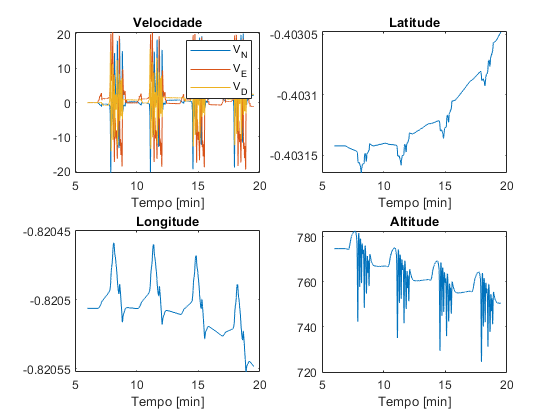

indexFim = struct with fields:
    volta1: 4778
    volta2: 9632
    volta3: 14800
    volta4: 19800


preProcessResults

## Análise da atitude computada pelo INS

**Vetor rotação**

    Calculou-se o vetor rotação ao final de cada volta com relação ao vetor original $q_0$, em [arcseg], de forma que

format shortG;
rotacaoFinalDeVolta = [
vetorRotacao(resultados.quaternion(indexFim.volta1,:), q0_base3),...
vetorRotacao(resultados.quaternion(indexFim.volta2,:), q0_base3),...
vetorRotacao(resultados.quaternion(indexFim.volta3,:), q0_base3),...
vetorRotacao(resultados.quaternion(indexFim.volta4,:), q0_base3)...
]*180/pi*3600

rotacaoFinalDeVolta =       -22.046      -23.934      -25.379      -3.9928
       8.2681       3.5578       14.204      -22.608
      -28.246      -154.12      -229.27         -235


**Índice de desalinhamento ao final de cada volta (escala log)**

    Analogamente, temos que os índices de desalinhamento dos quatérnions ao final de cada volta com relação ao quatérnion inicial $q_0$ são dados, em [arcseg], por

indiceDesalFinalDeVolta = [
indiceDesalinhamento(resultados.quaternion(indexFim.volta1,:), q0_base3),...
indiceDesalinhamento(resultados.quaternion(indexFim.volta2,:), q0_base3),...
indiceDesalinhamento(resultados.quaternion(indexFim.volta3,:), q0_base3),...
indiceDesalinhamento(resultados.quaternion(indexFim.volta4,:), q0_base3)...
]*180/pi*3600

indiceDesalFinalDeVolta =        36.773       156.01       231.11       236.12


**Comparação: índice de desalinhamento [arcseg] com magnitude do desalinhamento [arcseg] computado com quaternions**

normasRotacao = [
    norm(rotacaoFinalDeVolta(:,1)),...
    norm(rotacaoFinalDeVolta(:,2)),...
    norm(rotacaoFinalDeVolta(:,3)),...
    norm(rotacaoFinalDeVolta(:,4))...
    ];
format shortE
comparacaoMetricas = normasRotacao - indiceDesalFinalDeVolta

comparacaoMetricas =    3.5609e-07   3.6600e-08   1.3561e-08  -7.1943e-08


    De onde observa-se novamente, conforme conferido na análise dos resultados da Parte 2 desta lista, uma concordância entre as métricas de desalinhamento utilizadas (magnitude do vetor rotação e índice de desalinhamento) para o quatérnion de rotação de cada fim de volta em relação ao estado inicial.

## Análise da trajetória computada pelo INS

**Coordenadas geodésicas x cartesianas**

    Converteu-se as coordenadas geodésicas obtidas para coordenadas cartesianas no sistema ENU (*east north up*), que é similar ao NED, tomando como referência o ponto inicial do movimento (23° 05´ 54,04´´S, 47° 00´ 41,55´´W e altitude de 774,6707 m com respeito ao elipsoide WGS-84).

[xt,yt,zt] = geodToCart(...
    resultados.latitude,...
    resultados.longitude,...
    resultados.altitude,...
    modTerra);

**Resultado da altura contra tempo**

    Se tomada em relação ao ponto inicial, temos que a altura em função do tempo, em metros, pode ser dada por:

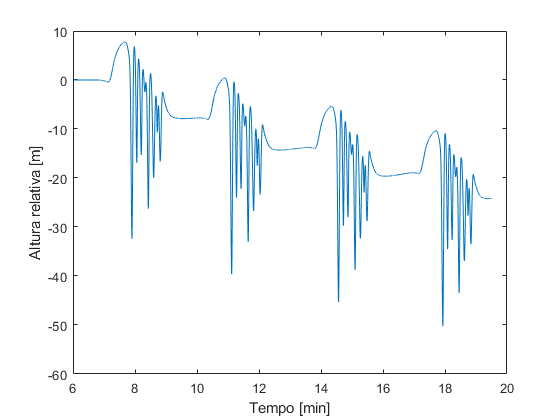

figure;
plot(resultados.tempo/60, zt)
xlabel("Tempo [min]");
ylabel("Altura relativa [m]");

**Gráfico tri-dimensional da trajetória computada pelo INS**

     A trajetória estimada pelo INS em relação ao ponto inicial, em metros, nas direções Norte, Leste e altitude a partir do instante inicial 0[s], em relação ao ponto inicial, é tal que

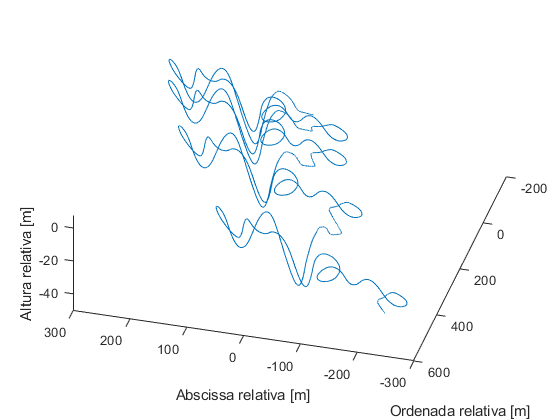

figure;
plot3(xt,yt,zt)
view([-164.7 63.4])
xlabel("Abscissa relativa [m]");
ylabel("Ordenada relativa [m]");
zlabel("Altura relativa [m]");

**Gráfico bi-dimensional da trajetória computada pelo INS**

     Em termos apenas de visualização no plano horizontal, temos, em coord cartersianas

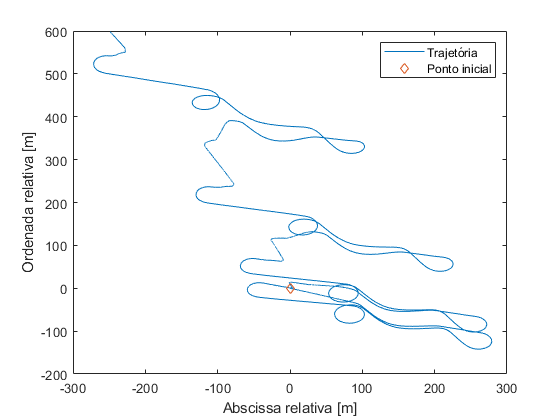

figure;
plot(xt,yt)
xlabel("Abscissa relativa [m]");
ylabel("Ordenada relativa [m]");
hold on;
plot(xt(indexInicio.volta1), yt(indexInicio.volta1), 'd');
legend('Trajetória', 'Ponto inicial');

## Comparação com a trajetória real

    Há, no primeiro experimento, um total de 4 voltas, das quais a primeira foi plotada abaixo separadamente como superposição à foto real da montanha russa Montezum, retirada do Google Earth, para fins de conferência de resultado. Em seguida, plotou-se o resultado obtido para as quatro voltas, de onde ainda se observa, assim como na Parte 2, a divergência da integração numérica quanto à latitude e à longitude para muitas iterações.

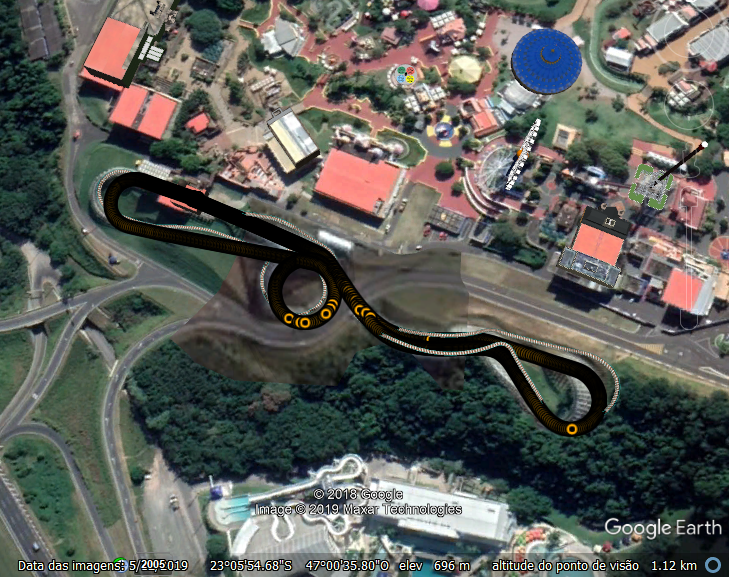

**Figura 05. **Superposição do resultado da integração numérica com a imagem real para a primeira volta.

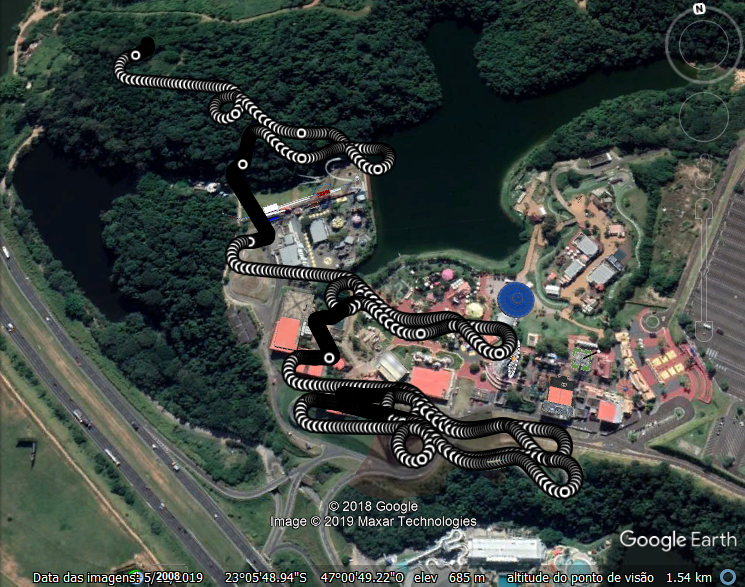

**Figura 06. **Superposição do resultado da integração numérica com a imagem real para as quatro voltas.

## **Erro horizontal e em altura**

    Com relação ao erro de posição relativa ao ponto inicial no plano horizontal e em altura ao final da primeira volta no primeiro experimento, temos os seguinte resultados, em metros:

format shortg
erroHorizontal = sqrt(xt(indexFim.volta1)^2 + yt(indexFim.volta1)^2)

erroHorizontal =        3.3084


erroAltura = zt(indexFim.volta1)

erroAltura =       -7.4582


    Note que a estabilização vertical vai ocasionar um erro de altura pequeno a depender dos ganhos a serem colocados no controlador.

## Apêndice

**Função de atualização de estado de Salichev**

function [y_new] = fs(t, y, omega_B_i, Asp_B_i, modTerra, estabVert, h_m, T)

    %% Preparação e inicializações auxiliares
    N = 1;
    E = 2;
    D = 3;

    R_0 = modTerra.R_0;
    e = modTerra.e;
    g_0 = modTerra.g_0;

    B = estabVert.B;
    C = estabVert.C;
    T_h = estabVert.T_h;

    Omega = 7.2921e-5;

    
    %% Mapeamento de variáveis
    q_NEDold_bold = y(1:4);
    V_NED = y(5:7);
    lat = y(8);
    lon = y(9);
    alt = y(10);
    h_aux = y(11);
    
    
    %% Passo 0: quaternion de rotação do NEDold para NEDnew a cada 4 amostras de freqüên-
    % cia rápida dos sensores inerciais, computado com frequência lenta.
    %% Modelo da Terra
    R_E = R_0*(1 + e*(sin(lat))^2);            % raio leste-oeste
    R_N = R_0*(1 - e*(2 - 3*(sin(lat))^2));    % raio norte-sul

    rho_NED = [...
        V_NED(E)/(R_E+alt), ...
        -V_NED(N)/(R_N+alt), ...
        -V_NED(E)/(R_E+alt)*tan(lat) ...
        ]';
    Omega_NED = [Omega*cos(lat),0,-Omega*sin(lat)]';

    omega_NEDi_NED = rho_NED + Omega_NED;  % taxa de transporte usa estimativas de velo-
                                           % cidade terrestre e posição mais recentes 
                                           % disponíveis 

    omega_versor = omega_NEDi_NED/norm(omega_NEDi_NED); % eixo de rotação instantânea 
                                                        % unitário

    q_NEDold_NEDnew = [...
         cos(norm(omega_NEDi_NED*4*T)/2);...
         omega_versor(:)*sin(norm(omega_NEDi_NED*4*T)/2)
         ];

     
    %% Passo 1: incremento da velocidade de empuxo \delta U_{f,b,k} computada com fre-
    % quência rápida. Índice k representa o instante inicial de um conjunto de 4 amos-
    % tras; k+1 o instante inicial do próximo conjunto de 4 amostras, sem superposição 
    % com o anterior.
    alpha(:,1) = omega_B_i(:,1);
    alpha(:,2) = omega_B_i(:,2);
    alpha(:,3) = omega_B_i(:,3);
    alpha(:,4) = omega_B_i(:,4);

    delta_beta(:,1) = Asp_B_i(:,1);
    delta_beta(:,2) = Asp_B_i(:,2);
    delta_beta(:,3) = Asp_B_i(:,3);
    delta_beta(:,4) = Asp_B_i(:,4);

    W_k_0 = zeros(3,1);   % W_k(0) = (0,0,0)^T
    W_k_old = W_k_0;

    for m=1:4 % sculling correction
        W_k_new = delta_beta(:,m) - cross(alpha(:,m), W_k_old) + W_k_old;
        W_k_new = delta_beta(:,m) - cross(alpha(:,m), W_k_new) + W_k_old;
        W_k_old = W_k_new;
    end

    delta_U_f_b_k = W_k_new;

    
    %% Passo 2: Incremento angular computado com quatro amostras incrementais e quaternion
    % de rotação q^{bold}_{bnew} do corpo na atitude anterior (bold) para o corpo na nova 
    % atitude (bnew). (new é a estampa de tempo k+1 e old é a estampa de tempo k).
    % coning correction
    P1 = crossToMatrix(alpha(:,1));
    P2 = crossToMatrix(alpha(:,2));
    P3 = crossToMatrix(alpha(:,3));
    P4 = crossToMatrix(alpha(:,4));

    delta_phi = alpha(:,1)+alpha(:,2)+alpha(:,3)+alpha(:,4)+...
        2/3*(P1*alpha(:,2)+P3*alpha(:,4))+...
        1/2*(P1+P2)*(alpha(:,3)+alpha(:,4))+...
        1/30*(P1-P2)*(alpha(:,3)-alpha(:,4));

    delta_phi_versor = delta_phi/norm(delta_phi);

    q_bold_bnew = [...
         cos(norm(delta_phi)/2);...
         delta_phi_versor(:)*sin(norm(delta_phi)/2)
         ];

    % quatérnion associado a \delta U_{f,b,k}
    delta_U_f_b_k_q = quat(delta_U_f_b_k);

    
    %% Passo 3: Computa em frequência lenta o quatérnion de rotação q^{NEDnew}_{bnew} 
    % mediante atualização de q^{bold}_{NEDold} devido à rotação de S_{NED} para posterior
    % transformação da força específica de S_b para S_{NED}. (new é a estampa de tempo k+1
    % e old é a estampa de tempo k).
    q_NEDnew_bnew = quatInv(...
        quatProd(...
            quatProd(...
                quatInv(q_bold_bnew), ...
                quatInv(q_NEDold_bold)), ...
            q_NEDold_NEDnew)...
        );
    delta_U_f_NED_k_q = quatProd(...
        quatProd(...
            q_NEDnew_bnew, ...
            delta_U_f_b_k_q), ...
        quatInv(q_NEDnew_bnew)...
        );

    
    %% Passo 4: Atualiza em baixa freqüência (a cada período 4T) velocidade terrestre e
    % posição. Usa posição (latitude, longitude e altitude) e velocidade terrestre V_{NED}
    % disponíveis para computar incremento de velocidade terrestre devido à gravidade.
    R_e = R_0*(1 - e*(sin(lat))^2);
    g = g_0*(1+.0053*(sin(lat))^2)*(1-2*alt/R_e);
    g_NED = [0,0,g]';

    delta_Vg_NED = (...
        -cross((rho_NED + 2*Omega_NED), V_NED) + ...
        g_NED + ...
        [0,0,B*(alt-h_aux)]'...
        )*4*T;
    delta_V_NED = delta_Vg_NED + quatToVector(delta_U_f_NED_k_q);
    V_NED = V_NED + delta_V_NED;  % atualiza V_{NED}

    V_N = V_NED(N);
    V_E = V_NED(E);
    V_D = V_NED(D);

    
    % Atualiza latitude, longitude e altitude para o próximo instante
    lat = lat + V_N/(R_N+alt)*4*T;
    lon = lon + V_E/((R_E+alt)*cos(lat))*4*T;
    alt = alt + -V_D*4*T - C*(alt-h_aux)*4*T;
    h_aux = h_aux + (h_m-h_aux)/T_h*4*T;
    
    y_new = [...
        q_NEDnew_bnew; ...
        V_NED; ...
        lat; ...
        lon; ...
        alt; ...
        h_aux ...
    ];
end